# ECEN 611 Homework 3: Winding Factor and Inductance

`Shuxuan Chen | 132006082 | Fall 2024`

*Last updated: Sep 29*

clearvars 
clc 

## Problem 1: Winding Factor 

Verify the harmonic winding factor for the fractional pitch, uniformly distributed winding.

T = 2*pi;
NT = 1;    % number of turns 

### Full Pitch, Concentrated Two-Pole Winding  

#### Counting Function

syms phi  
countingFun = piecewise( phi >= 0      & phi <  pi/3,    0, ...
                         phi >= pi/3   & phi <  4*pi/3, -NT, ...
                         phi >= 4*pi/3 & phi <= T,       0)

$$countingFun = \left\{ \begin{array}{cl} 0 & \text{ if }\varphi \in \left[0,\frac{\pi }{3}\right)\\ -1 & \text{ if }\varphi \in \left[\frac{\pi }{3},\frac{4\,\pi }{3}\right)\\ 0 & \text{ if }\varphi \in \left[\frac{4\,\pi }{3},2\,\pi \right] \end{array}\right.$$

#### (Figure) Counting Function

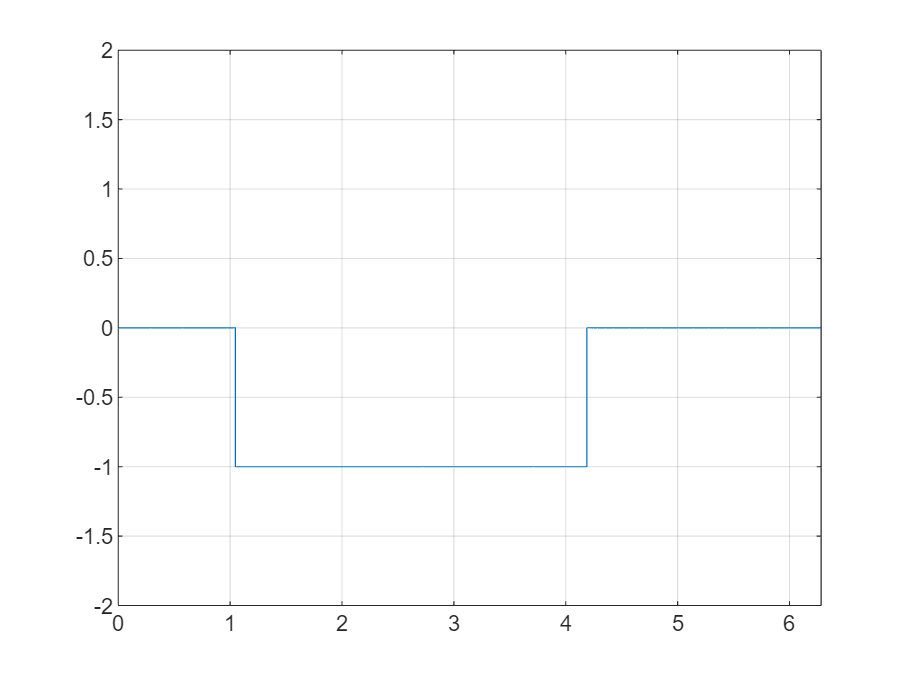

fplot(countingFun, [0 2*pi])
ylim([-2 2])
grid 

countingFun_avg = 1/T * int(countingFun, phi, [0 T]);

#### Winding Function

windingFun = countingFun - countingFun_avg;
windingFun = piecewise( ...    
    phi <= 0,            subs(windingFun, phi, phi+T), ...
    phi >= 0 & phi <= T, windingFun, ...         
    phi > T,             subs(windingFun, phi, phi-T) ... % I'm a genius!!
);

#### (Figure) Counting Function and Winding Function

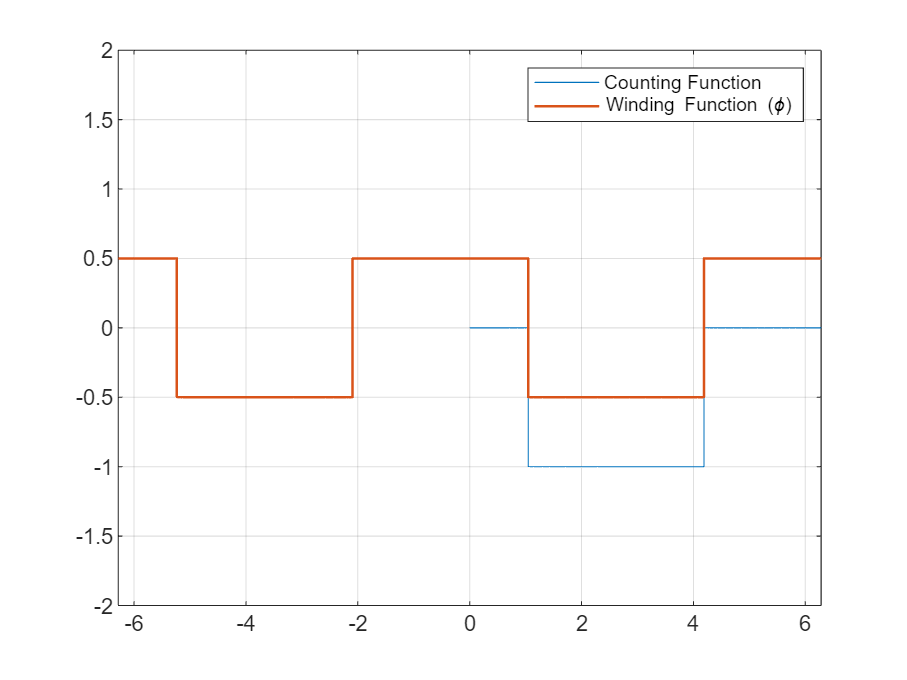

figure 
fplot(countingFun, [0 2*pi], "DisplayName", "Counting Function")
hold on 
fplot(windingFun, [-2*pi 2*pi], ...
    "LineWidth", 1.2, ...
    "DisplayName", "Winding Function (\phi)")
hold off 
ylim([-2 2])
legend 
grid 

#### Centralized Winding Function

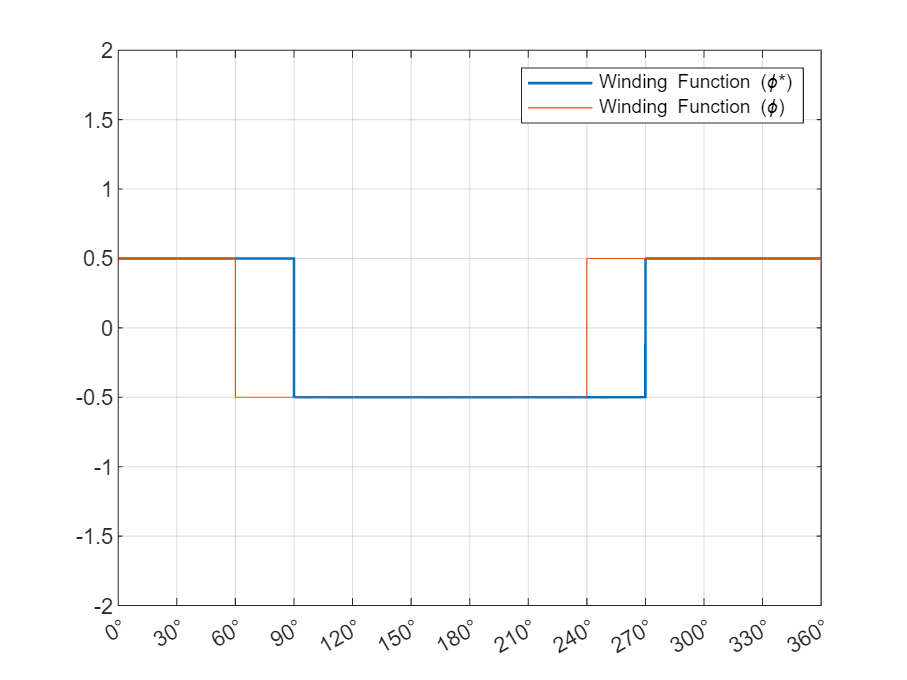

shiftAngle = T/4 - pi/3; % How to relate 4 to the number of poles?
windingFun_star = subs(windingFun, phi, phi - shiftAngle);

figure 
fplot(windingFun_star, [0 2*pi], "LineWidth", 1.2, "DisplayName", "Winding Function (\phi*)")
hold on 
fplot(windingFun, [0 2*pi], "DisplayName", "Winding Function (\phi)")
ylim([-2 2])
grid 
legend
% Customize x-tick labels to show degrees with increments of 30 degrees
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0°', '30°', '60°', '90°', '120°', '150°', '180°', '210°', '240°', '270°', '300°', '330°', '360°'});

#### Winding Function in Fourier Series

num_harmonics = 7;
h = 1:num_harmonics;
digits(4)

% a0 = vpa( (1/T)*int(windingFun, phi, 0, T), 4 )
% b = (2/T)*int(expression*sin(k*theta), theta, 0, T);
% Nch = a

% windingFun_star = piecewise( phi >= 0      & phi <  pi/2,    NT/2, ...
%                              phi >= pi/2   & phi <  3*pi/2, -NT/2, ...
%                              phi >= 3*pi/2 & phi <= T,       NT/2);

a0 = vpa( (1/T)*int(windingFun, phi, 0, T), 4 )

$$a0 = 1.819e-12$$

a  = vpa( (2/T)*int(windingFun_star*cos(h*phi), phi, 0, T) );
b  = vpa( (2/T)*int(windingFun_star*sin(h*phi), phi, 0, T) )

$$b = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

#### Nch: My Result

Nch = a

$$Nch = \left(\begin{array}{ccccccc} 0.6366 & 0 & -0.2122 & 0 & 0.1273 & 0 & -0.09095 \end{array}\right)$$

### 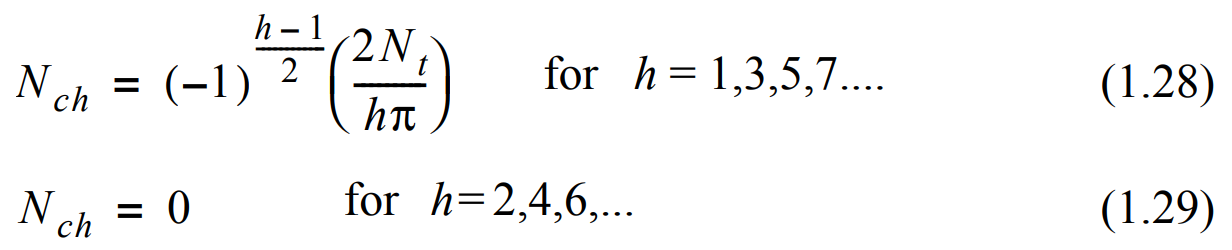

#### Nch: Textbook Result

Nch_ref = real( (-1).^((h-1)/2).*(2*NT./(h*pi)) )

Nch_ref =     0.6366         0   -0.2122         0    0.1273         0   -0.0909


### Full Pitch, Uniformly Distributed 2-Pole Winding

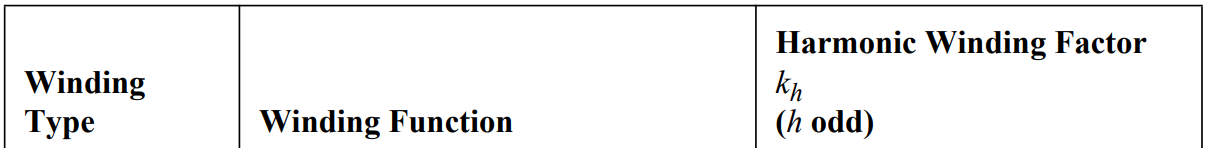

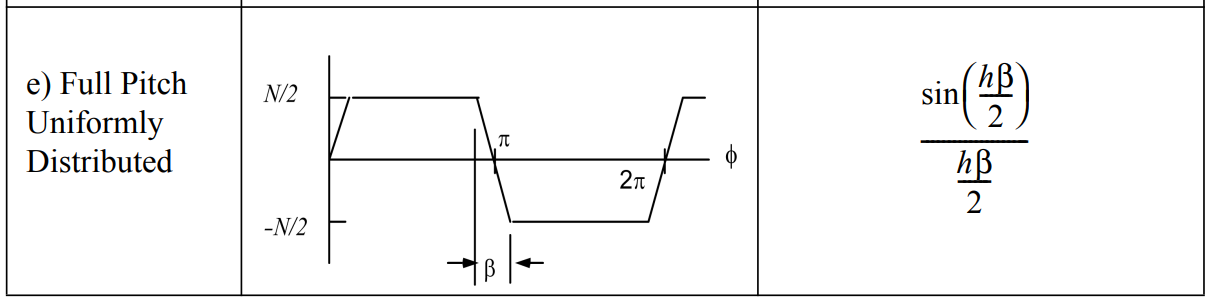

#### Counting Function

% windingFun_star
syms beta N_t
windingDensity = N_t/beta

$$windingDensity = \frac{N_{t}}{\beta }$$

countingFun = piecewise( ...
    phi >= 0         & phi <      beta, windingDensity * phi, ... % for 0 ≤ φ ≤ β
    phi >= beta      & phi <        pi, N_t, ...
    phi >= pi        & phi < pi + beta, -windingDensity*(phi-pi) + N_t, ...
    phi >= pi + beta & phi <=     2*pi, 0 ...
) 

$$countingFun = \left\{ \begin{array}{cl} \frac{N_{t}\,\varphi }{\beta } & \text{ if }\varphi <\beta \wedge 0\leq \varphi \\ N_{t} & \text{ if }\varphi <\pi \wedge \beta \leq \varphi \\ N_{t}-\frac{N_{t}\,\left(\varphi -\pi \right)}{\beta } & \text{ if }\pi \leq \varphi \wedge \varphi <\beta +\pi \\ 0 & \text{ if }\varphi \leq 2\,\pi \wedge \beta +\pi \leq \varphi \end{array}\right.$$

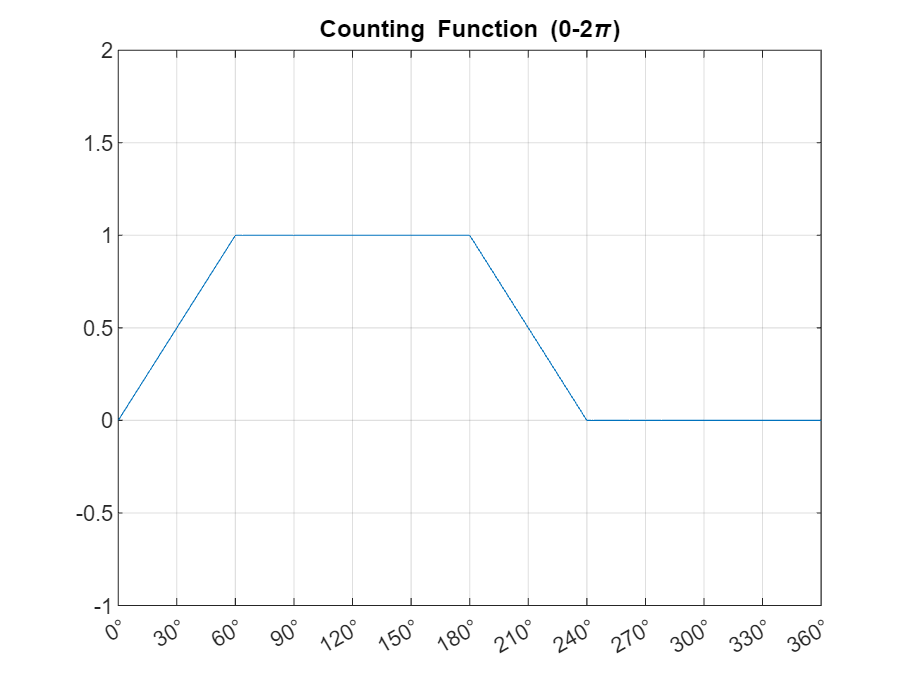

countingFun = subs(countingFun, [beta N_t], [pi/3 1]);

figure 
fplot(countingFun, [0 2*pi])
title("Counting Function (0-2\pi)")
ylim([-1 2])
grid 
% Customize x-tick labels to show degrees with increments of 30 degrees
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0°', '30°', '60°', '90°', '120°', '150°', '180°', '210°', '240°', '270°', '300°', '330°', '360°'});

% countingFun = piecewise( ...
%     phi >= 0 & phi <= T, countingFun, ...         
%     phi > T, subs(countingFun, phi, phi-T) ... % I'm a genius!!
% )
% figure 
% fplot(countingFun, [0 4*pi])
% title("Counting Function Extended (0-4\pi)")
% ylim([-1 2])
% grid 

% Customize x-tick labels to show degrees with increments of 30 degrees
% xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
% xticklabels({'0°', '30°', '60°', '90°', '120°', '150°', '180°', '210°', '240°', '270°', '300°', '330°', '360°'});

countingFun_avg = 1/T * int(countingFun, phi, [0 T]);

#### Winding Function

windingFun = countingFun - countingFun_avg;
windingFun = piecewise( ...    
    phi <= 0,            subs(windingFun, phi, phi+T), ...
    phi >= 0 & phi <= T, windingFun, ...         
    phi > T,             subs(windingFun, phi, phi-T) ... % I'm a genius!!
);

#### Centralized Winding Function

windingFun_star = subs(windingFun, phi, phi+pi/2+beta/2); % need to generalize this shift angle 
windingFun_star = subs(windingFun_star, beta, pi/3);

#### (Figure) Counting Function and Winding Function 

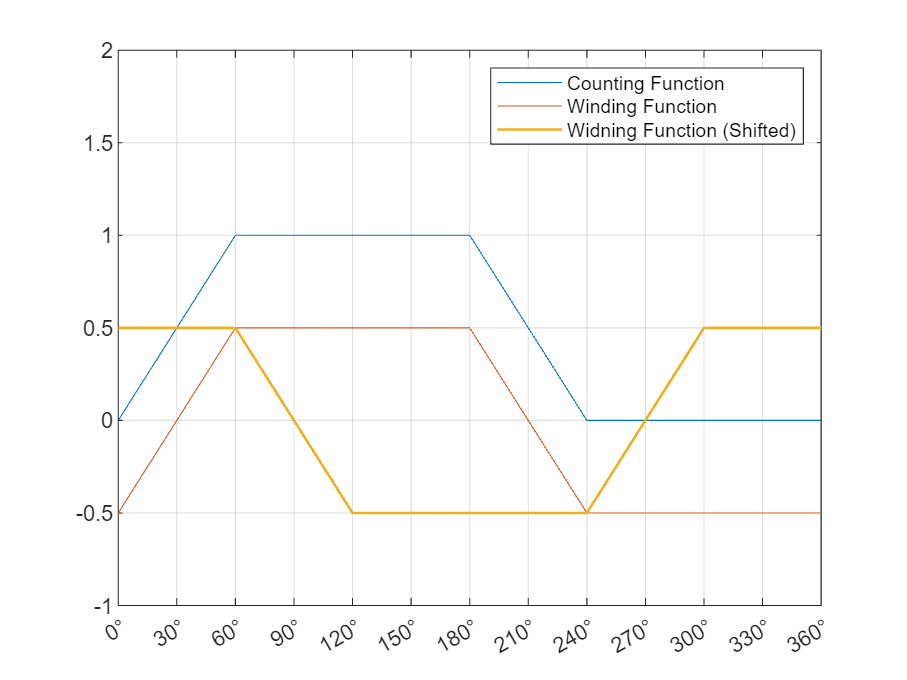

figure 
fplot(countingFun, [0 2*pi], "DisplayName", "Counting Function")
hold on 
fplot(windingFun, [0 2*pi], "DisplayName", "Winding Function")
fplot(windingFun_star, [0 2*pi], "LineWidth", 1.2, "DisplayName", "Widning Function (Shifted)")
hold off 
ylim([-1 2])
legend
grid 

% Customize x-tick labels to show degrees with increments of 30 degrees
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0°', '30°', '60°', '90°', '120°', '150°', '180°', '210°', '240°', '270°', '300°', '330°', '360°'});

#### Nh: My Result

Nh = vpa( (2/T)*int(windingFun_star*cos(h*phi), phi, 0, T) )

$$Nh = \left(\begin{array}{ccccccc} 0.6079 & 0 & -0.1351 & 0 & 0.02432 & 0 & 0.01241 \end{array}\right)$$

#### Nh: Textbook Result

Nh_ref = (-1).^((h-1)/2).*(2*NT./(h*pi)).*sin(h*beta/2)./(h*beta/2);
Nh_ref = vpa( real( subs(Nh_ref, beta, pi/3) ) )

$$Nh\_ref = \left(\begin{array}{ccccccc} 0.6079 & 0 & -0.1351 & 0 & 0.02432 & 0 & 0.01241 \end{array}\right)$$

### Fractional Pitch, Uniformly Distributed Two-Pole Winding 

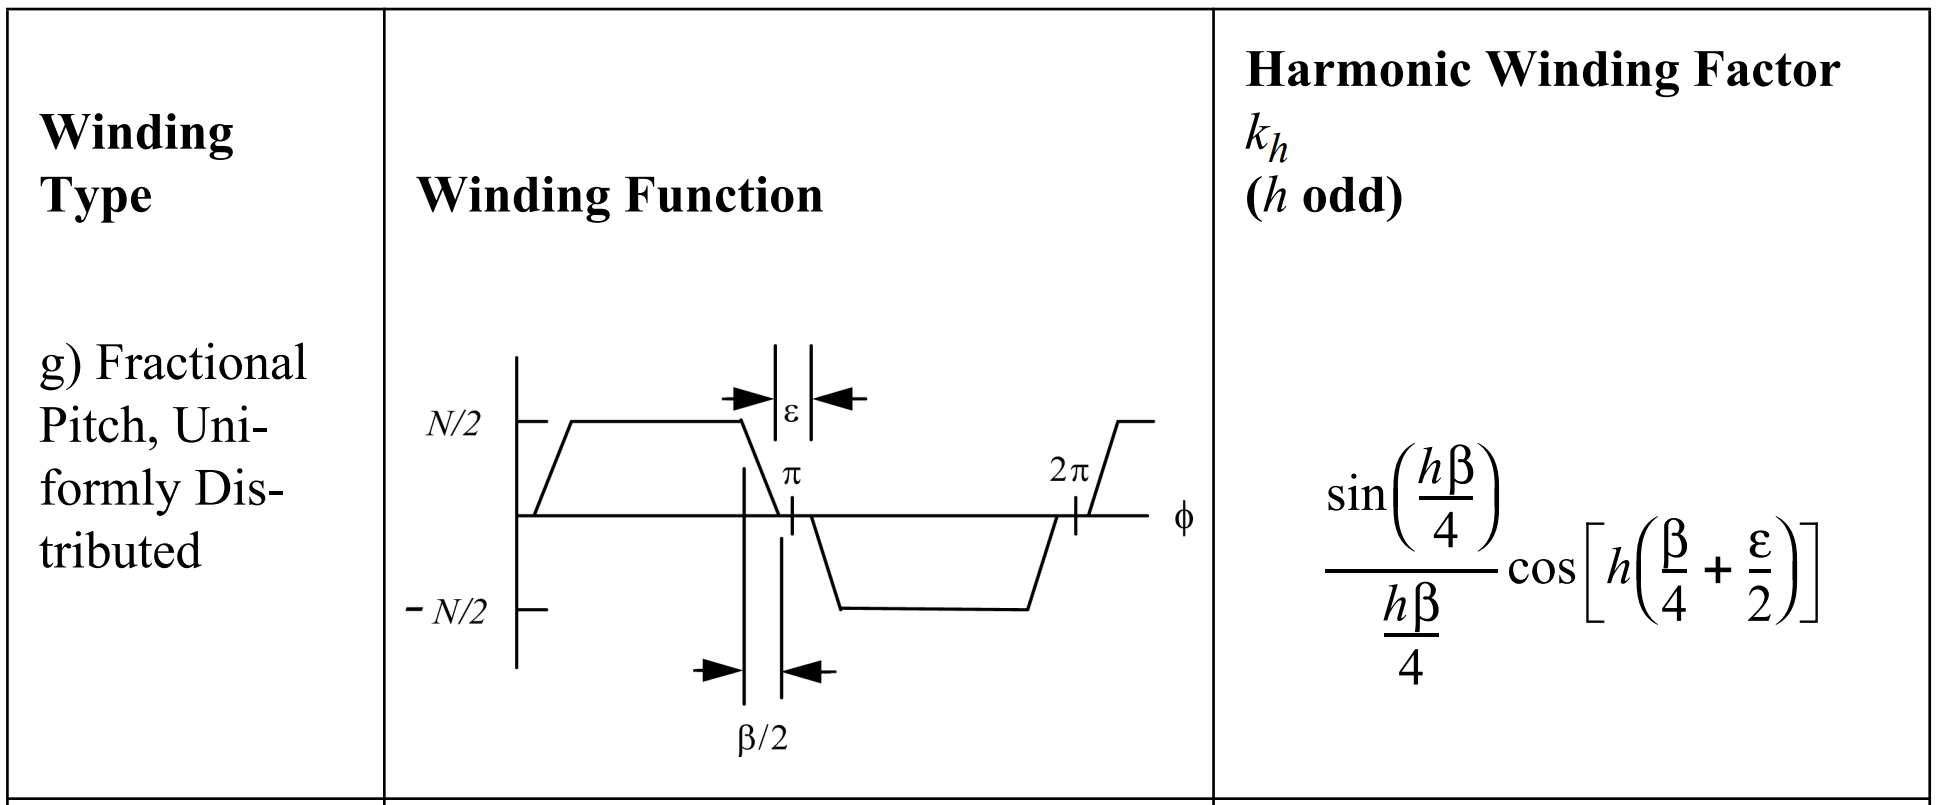

#### Winding Function

syms epsilon
windingFun_star = piecewise( ...
    phi >= 0                       & phi < epsilon/2, 0, ...
    phi >= epsilon/2               & phi < epsilon/2 + beta/2, N_t/beta*(phi-epsilon/2), ...
    phi >= epsilon/2 + beta/2      & phi < pi - epsilon/2 - beta/2, N_t/2, ...
    phi >= pi - epsilon/2 - beta/2 & phi < pi - epsilon/2, -N_t/beta*(phi-(pi-epsilon/2)), ...
    phi >= pi - epsilon/2          & phi < pi, 0 ...
);

% windingFun_star = subs(windingFun_star, [N_t beta epsilon], [NT pi/6 pi/12]);
% figure
% fplot(windingFun_star, [0 2*pi])
% ylim([-1 1])
% grid 
windingFun_star = piecewise( ...
    phi >= 0  & phi <= T/2, windingFun_star, ...         
    phi > T/2 & phi <= T,  -subs(windingFun_star, phi, phi-pi) ... % I'm a genius!!
);

#### (Figure) Winding Function

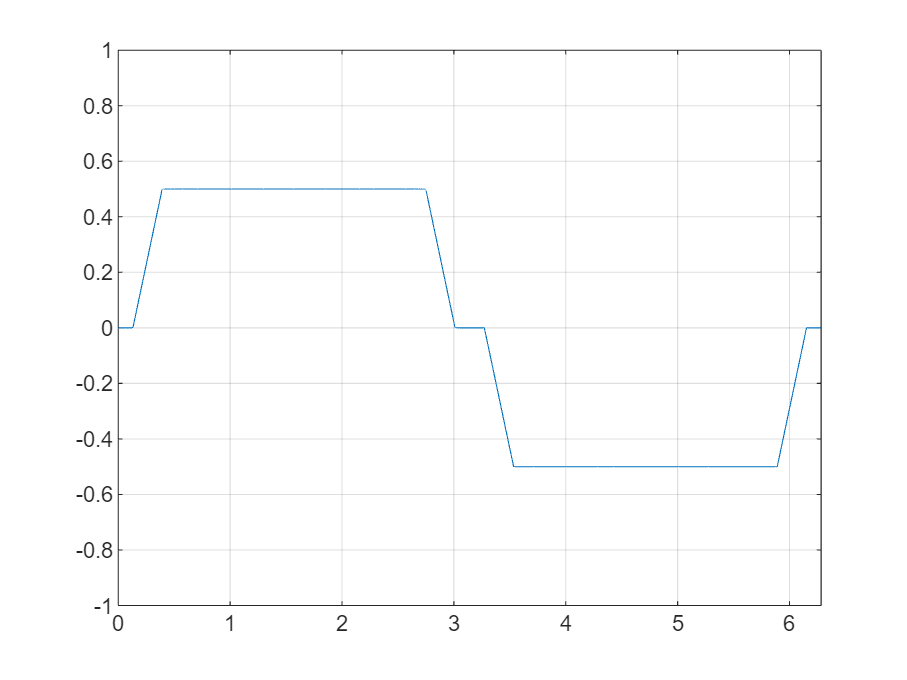

figure
fplot(subs(windingFun_star, [N_t beta epsilon], [NT pi/6 pi/12]), [0 2*pi]);
ylim([-1 1])
grid 

#### Nh: My Result

windingFun_star = subs(windingFun_star, [N_t beta epsilon], [NT pi/6 pi/12]);

Nh = vpa( (2/T)*int(windingFun_star*sin(h*phi), phi, 0, T) )

$$Nh = \left(\begin{array}{ccccccc} 0.6132 & 0 & 0.1462 & 0 & 0.03065 & 0 & -0.02038 \end{array}\right)$$

windingFun_star_rec = sum(Nh.*sin(h.*phi));

#### Nh: Textbook Result

Nh_ref = sin(h*beta/4)./(h*beta/4) .* cos(h*(beta/4+epsilon/2)); % <-- What's its reference?
Nh_ref = vpa( subs(Nh_ref.*Nch_ref, [beta epsilon], [pi/6 pi/12]) ) 

$$Nh\_ref = \left(\begin{array}{ccccccc} 0.6132 & 0 & -0.1462 & 0 & 0.03065 & 0 & 0.02038 \end{array}\right)$$

#### (Figure) Validation of Fourier Series through Reconstruction

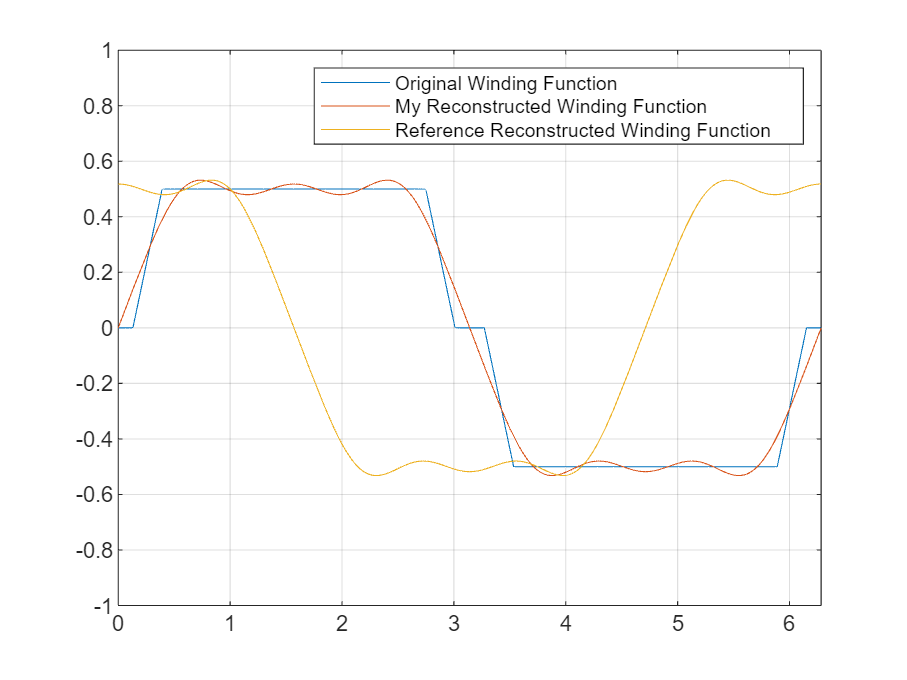

figure 
fplot(windingFun_star, [0 2*pi], "DisplayName", "Original Winding Function")
hold on 
fplot(windingFun_star_rec, [0 2*pi], "DisplayName", "My Reconstructed Winding Function")
fplot(sum(Nh_ref.*cos(h.*phi)), [0 2*pi], "DisplayName", "Reference Reconstructed Winding Function")
hold off 
ylim([-1 1])
grid 
legend 

## Problem 2: Magnetizing Inductance  

Calculate the magnetizing inductance of the above winding (fractional pitch, uniformly distributed 2-pole winding).

Textbook pg. 31

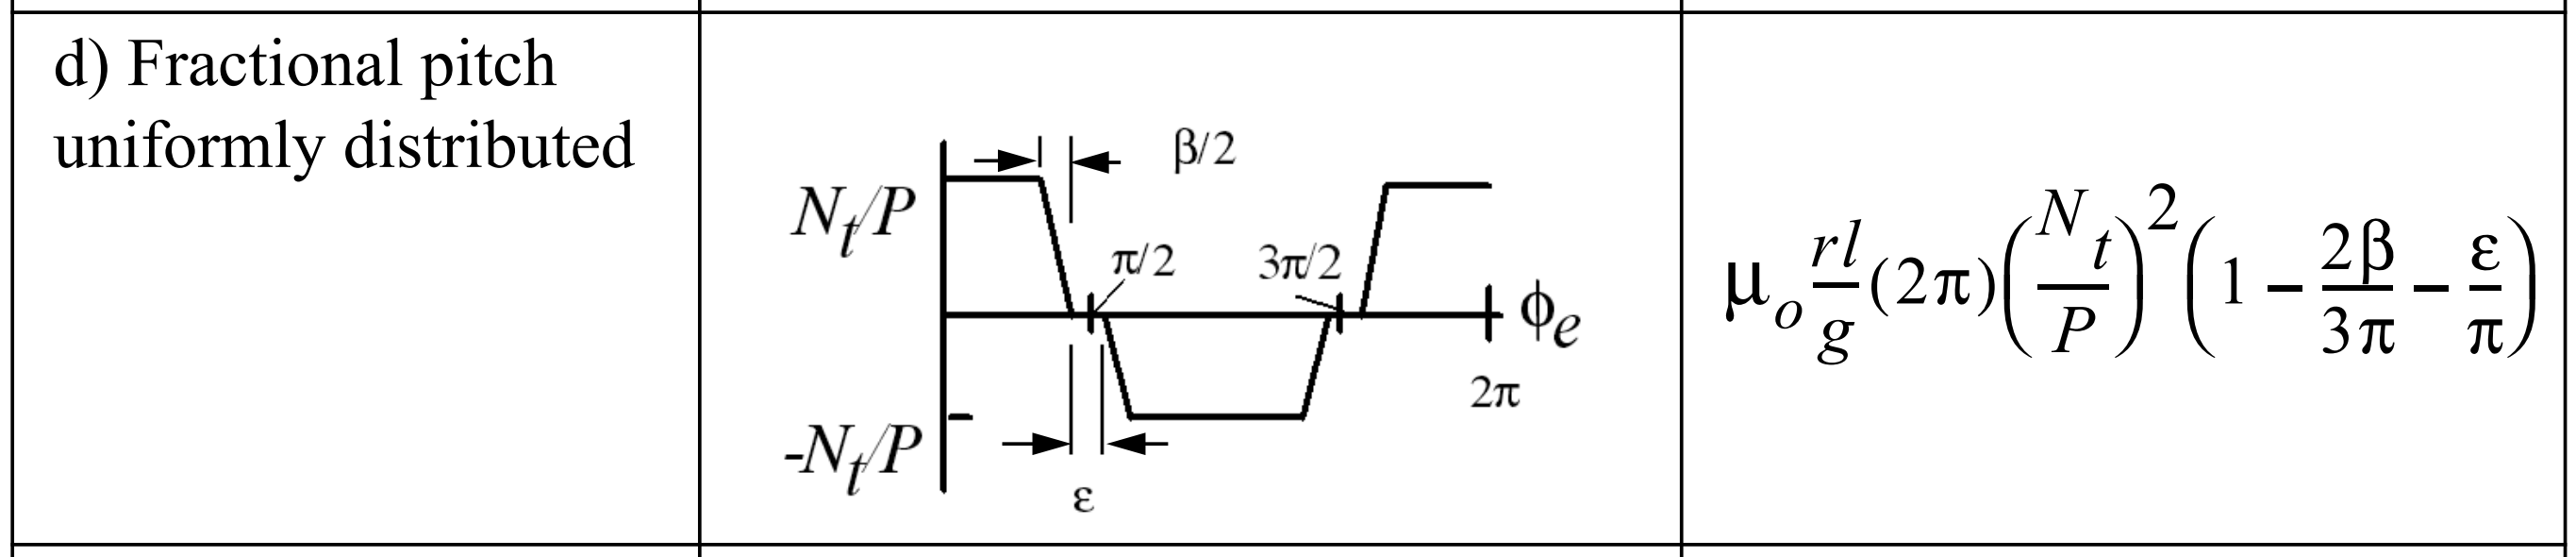

### Winding Function

syms epsilon P
windingFun_star = piecewise( ...
    phi >= 0                       & phi < epsilon/2, 0, ...
    phi >= epsilon/2               & phi < epsilon/2 + beta/2, (N_t/P)/(beta/2)*(phi-epsilon/2), ...
    phi >= epsilon/2 + beta/2      & phi < pi - epsilon/2 - beta/2, N_t/P, ...
    phi >= pi - epsilon/2 - beta/2 & phi < pi - epsilon/2, -(N_t/P)/(beta/2)*(phi-(pi-epsilon/2)), ...
    phi >= pi - epsilon/2          & phi < pi, 0 ...
);

windingFun_star = piecewise( ...
    phi >= 0  & phi <= T/2, windingFun_star, ...         
    phi > T/2 & phi <= T,  -subs(windingFun_star, phi, phi-pi) ...
);

### (Figure) Winding Function

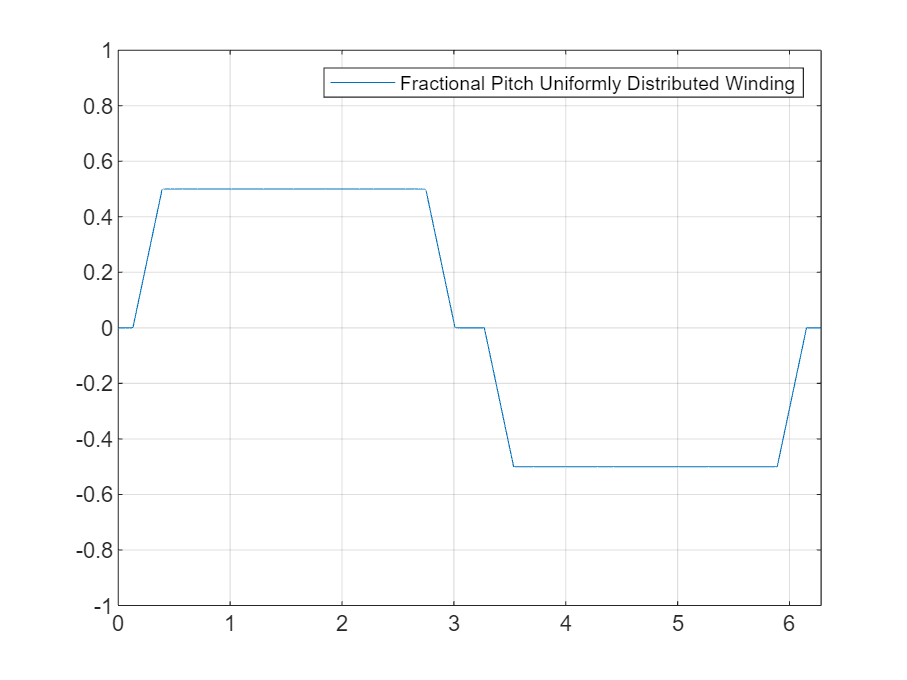

syms mu_o r l g

windingFun_star = subs( windingFun_star, [beta epsilon], [pi/6 pi/12] );

figure
fplot(subs(windingFun_star, [N_t P], [1 2]), [0 2*pi], ...
    "DisplayName", "Fractional Pitch Uniformly Distributed Winding")
hold off 
ylim([-1 1])
grid 
legend 

### Magnetizing Inductance

#### My Result

LAA = mu_o*r*l/g * int( windingFun_star^2, phi, [0 2*pi] ) 

$$LAA = \frac{29\,\pi \,{N_{t}}^{2}\,l\,\mu_{o}\,r}{18\,P^{2}\,g}$$

#### Textbook Result

LAA_ref = subs( (mu_o*r*l/g) * (2*pi) * (N_t/P)^2 * (1 - 2*beta/(3*pi) - epsilon/pi), ...
                [beta epsilon], ...
                [pi/6 pi/12] )

$$LAA\_ref = \frac{29\,\pi \,{N_{t}}^{2}\,l\,\mu_{o}\,r}{18\,P^{2}\,g}$$

## Problem 3: Mutual Inductance  

Verify the mutual inductance between a (full pitch) uniformly distributed and a sinusoidally distributed winding each with P poles.

### Winding Function of Sinusoidally Distributed P-Pole Winding

% syms phi
syms N_sin
windingFun_sin = N_sin/P * sin(P/2*phi)

$$windingFun\_sin = \frac{N_{\sin}\,\sin\left(\frac{P\,\varphi }{2}\right)}{P}$$

### Winding Function of (Full Pitch) Uniformly Distributed P-Pole Winding

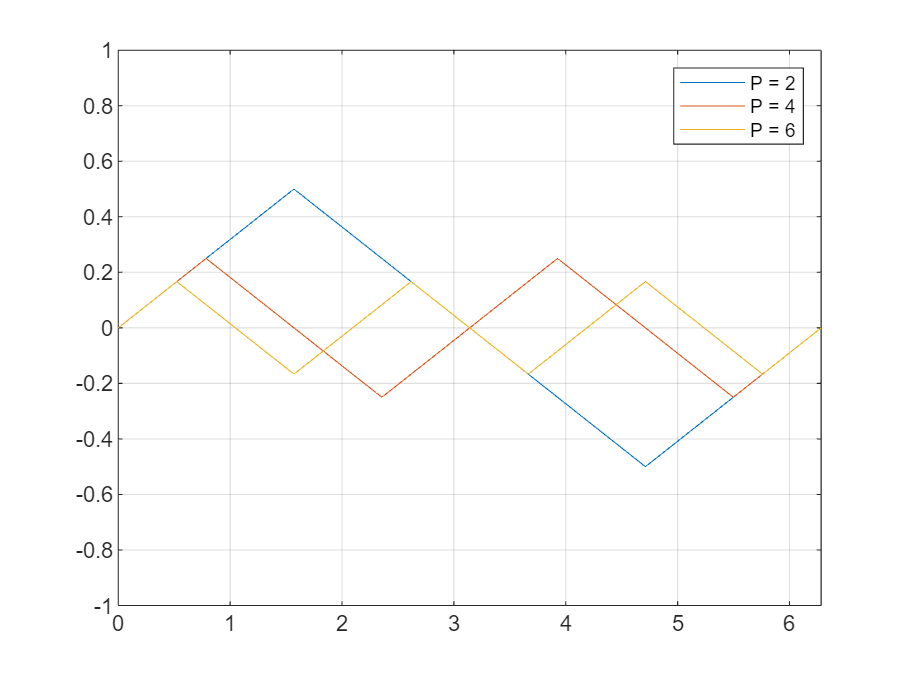

intv = T/(2*P); 
slope = (N_t/P)/intv;
t = 4*intv; 

windingFun_fp_uni = piecewise( ...
    phi >= 0        & phi < intv,    slope * (phi), ...
    phi >= intv     & phi < 3*intv,  -slope * (phi-intv) + N_t/P, ...
    phi >= 3*intv   & phi < t,  slope * (phi-3*intv) - N_t/P ...
);
    
windingFun_fp_uni_ext = piecewise( ...
    phi >= 0 & phi < t, windingFun_fp_uni, ...
    phi >= t, subs(windingFun_fp_uni, phi, phi-t), ...
    phi >= 2*t, subs(windingFun_fp_uni, phi, phi-2*t) ...
);

figure 

for numberOfPoles = 2:2:6
    % Substitute P directly in the symbolic expression
    fplot(subs(windingFun_fp_uni_ext, [N_t P], [1 numberOfPoles]), [0 2*pi], ...
    'DisplayName', sprintf('P = %d', numberOfPoles))  % Use sprintf to format DisplayName
    hold on
end

ylim([-1 1])
hold off 
grid 
legend 

### (Figure) Winding Functions of Interest

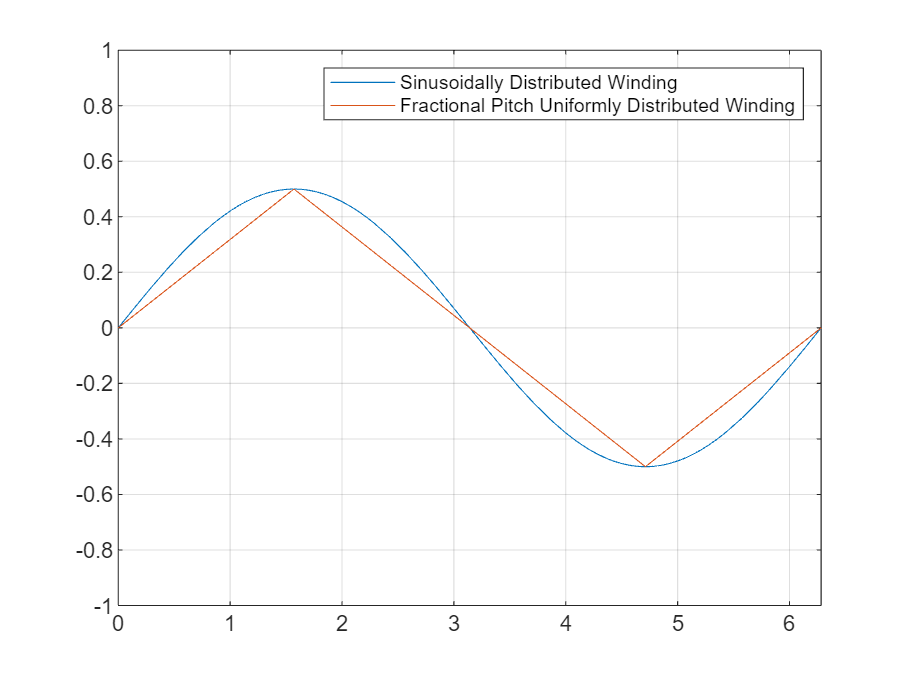

figure 
fplot(subs(windingFun_sin, [N_sin P], [1 2]), [0 2*pi], ...
    "DisplayName", "Sinusoidally Distributed Winding")
hold on
fplot(subs(windingFun_fp_uni_ext, [N_t P], [1 2]), [0 2*pi], ...
    "DisplayName", "Fractional Pitch Uniformly Distributed Winding")
hold off 
ylim([-1 1])
grid 
legend 

### Mutual Inductance 

#### My Result

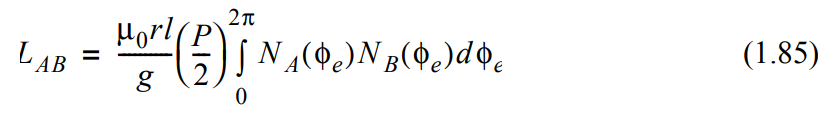

% Use equation 1.85
assume(P >= 2 & mod(P, 2) == 0);
L_uniform_sin = (mu_o*r*l/g) * (P/2) * int( windingFun_sin*windingFun_fp_uni, ...
                                            phi, [0 2*pi]);

L_uniform_sin = simplify(L_uniform_sin)

$$L\_uniform\_sin = \frac{8\,N_{\sin}\,N_{t}\,l\,\mu_{o}\,r}{P^{2}\,g\,\pi }$$

#### Textbook Result

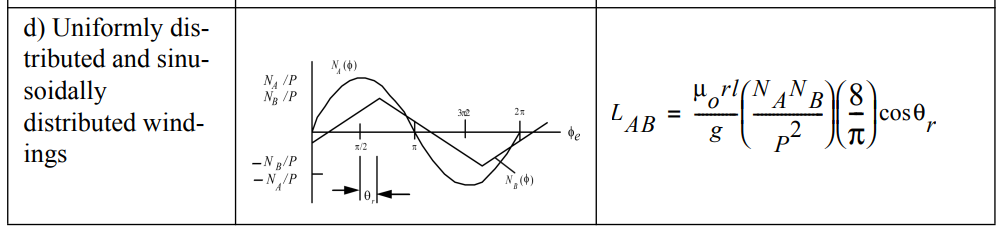

syms theta_r 
L_uniform_sin_ref  = (mu_o*r*l/g) * (N_t*N_sin/P^2) * (8/(sym(1)*pi)) * subs(cos(theta_r), theta_r, 0)

$$L\_uniform\_sin\_ref = \frac{8\,N_{\sin}\,N_{t}\,l\,\mu_{o}\,r}{P^{2}\,g\,\pi }$$

## Problem 4

A **uniform air-gap** machine has an axial length of 1m, a rotor radius of 0.5 m, and a gap length of 0.50 cm. The rotor and the stator are each wound with a sinusoidally distributed 4-pole winding with 50 turns per pole. If the rotor and stator coil axes are aligned and the two windings connected in series, how much current should be passed through the windings to produce a peak air-gap flux density of 0.8 weber/m2?

### Parameters

LENGTH = 1;      % m
RADIUS = 0.5;    % m
GAP    = 0.5e-2; % m

N_POLE       = 4;
N_TURN_POLE  = 50;
N_TURN_TOTAL = N_POLE*N_TURN_POLE;

B_PEAK = 0.8;    % Weber/m^2

- sinusoidally distributed 4-pole winding

- uniform air-gap 

- rotor and stator coil axes are aligned => theta_r = 0, cos(theta_r) = 1

- two windings connected in series (, respectively?)

- Do I need to calculate magnetizing and mutual inductance?

uo = 4*pi*1e-7  % H/m

uo = 1.2566e-06

% magnetic flux density  : T = Wb/m^2 = N/(A·m)
% permeability           : H/m N/A^2
% magnetic field strength: A/m
H_PEAK = B_PEAK / uo     % A/m = N/(A·m)/(N/A^2)

H_PEAK = 6.3662e+05

syms N A m 
N/(A*m)/(N/A^2)

$$ans = \frac{A}{m}$$

MMF_PEAK = H_PEAK*GAP 

MMF_PEAK = 3.1831e+03

### Winding Functions

% Stator
% winding function 
stator_windingFun_sin = subs( windingFun_sin, [N_sin P], [N_TURN_TOTAL N_POLE] )

$$stator\_windingFun\_sin = 50\,\sin\left(2\,\varphi \right)$$

% Rotor winding function 
rotor_windingFun_sin  = stator_windingFun_sin;

### *Inductances

% magnetizing inductance
stator_Lm = mu_o*r*l/g * (N_POLE/2) * int( stator_windingFun_sin^2, phi, [0 2*pi] );
stator_Lm = vpa( subs(stator_Lm, [l mu_o r g], [LENGTH uo RADIUS GAP]) ) % H

$$stator\_Lm = 1.974$$

rotor_Lm = stator_Lm

$$rotor\_Lm = 1.974$$

% stator-rotor mutual inductance 
L_stator_rotor = mu_o*r*l/g * (N_POLE/2) * int( stator_windingFun_sin*rotor_windingFun_sin, phi, [0 2*pi] );
L_stator_rotor = vpa( subs(L_stator_rotor, [l mu_o r g], [LENGTH uo RADIUS GAP]) ) % H

$$L\_stator\_rotor = 1.974$$

### Composite Airgap MMF

syms I
stator_MMF = stator_windingFun_sin * I;
rotor_MMF  = rotor_windingFun_sin * I;
composite_MMF  = stator_MMF + rotor_MMF

$$composite\_MMF = 100\,\text{I}\,\sin\left(2\,\varphi \right)$$

Find the location where MMF reaches its peak value

[peak_phi, peak_MMF] = fminbnd(@(phi) -sin(2*phi), 0, 2*pi); % Find the minimum of the negative function
peak_MMF = -peak_MMF  % Get the maximum value

peak_MMF = 1.0000

% MATLAB does not have an fmaxbnd function because finding a maximum is simply a variant of finding a minimum, which is already handled by the function fminbnd. 
% To find the maximum, you can negate the function and use fminbnd to minimize the negated function.

Find peak MMF (symbolic)

total_MMF_peak = vpa( subs(composite_MMF, phi, peak_phi) )

$$total\_MMF\_peak = 100.0\,\text{I}$$

### Current

current = solve(total_MMF_peak==MMF_PEAK) % A

$$current = 31.83$$